1.

clear,clc,close all
syms V1 V2 I0 Ia Ib Ic Id V0 Ra Cb Cc Rd s R C f
eqn1 = V0-V1==Ia*Ra;
eqn2 = Ib==Cb*s*(V0-V2);
eqn3 = Ic==Cc*s*(V1-V2);
eqn4 = V2==Id*Rd;
eqn5 = I0==Ia+Ib;
eqn6 = Ia==Ic;
eqn7 = Ib+Ic==Id;
A = solve(eqn1,eqn2,eqn3,eqn4,eqn5,eqn6,eqn7,V1,V2,I0,Ia,Ib,Ic,Id);
Gs = simplify(A.V1)/V0

$$Gs = \frac{\mathrm{Cb}\,\mathrm{Rd}\,s+\mathrm{Cc}\,\mathrm{Rd}\,s+\mathrm{Cb}\,\mathrm{Cc}\,\mathrm{Ra}\,\mathrm{Rd}\,s^{2}+1}{\mathrm{Cc}\,\mathrm{Ra}\,s+\mathrm{Cb}\,\mathrm{Rd}\,s+\mathrm{Cc}\,\mathrm{Rd}\,s+\mathrm{Cb}\,\mathrm{Cc}\,\mathrm{Ra}\,\mathrm{Rd}\,s^{2}+1}$$

M = [1 0 0 Ra 0 0 0;0 Cb*s 0 0 1 0 0;Cc*s -Cc*s 0 0 0 -1 0;0 1 0 0 0 0 -Rd;0 0 1 -1 -1 0 0;0 0 0 1 0 -1 0;0 0 0 0 1 1 -1];
b = [V0;Cb*s*V0;0;0;0;0;0];
x = M\b;
GsFromMat = simplify(x(1))/V0

$$GsFromMat = \frac{\mathrm{Cb}\,\mathrm{Rd}\,s+\mathrm{Cc}\,\mathrm{Rd}\,s+\mathrm{Cb}\,\mathrm{Cc}\,\mathrm{Ra}\,\mathrm{Rd}\,s^{2}+1}{\mathrm{Cc}\,\mathrm{Ra}\,s+\mathrm{Cb}\,\mathrm{Rd}\,s+\mathrm{Cc}\,\mathrm{Rd}\,s+\mathrm{Cb}\,\mathrm{Cc}\,\mathrm{Ra}\,\mathrm{Rd}\,s^{2}+1}$$

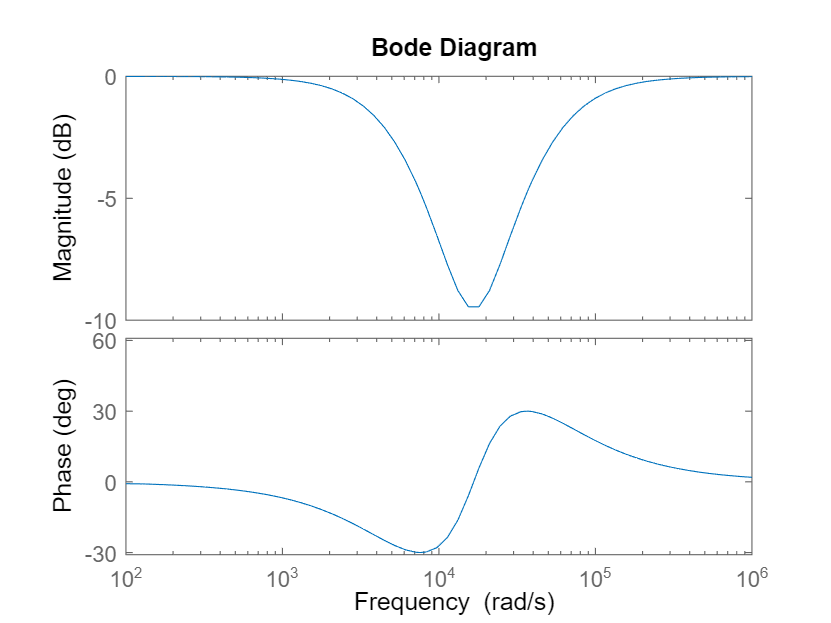

C = 3e-6;R=20;
bode(tf([1 1/(C*R) 1/(C*R)^2],[1 3/(C*R) 1/(C*R)^2]))

2.

clear,clc
syms V1 V2 I0 Ia Ib Ic Id V0 Ca Rb Rc Cd s R C 
eqn1 = Ia==Ca*s*(V0-V1);
eqn2 = V0-V2==Ib*Rb;
eqn3 = V1-V2==Ic*Rc;
eqn4 = Id==Cd*s*V2;
eqn5 = I0==Ia+Ib;
eqn6 = Ia==Ic;
eqn7 = Ib+Ic==Id;
B = solve(eqn1,eqn2,eqn3,eqn4,eqn5,eqn6,eqn7,V1,V2,I0,Ia,Ib,Ic,Id);
Gs2 = simplify(B.V1)/V0

$$Gs2 = \frac{\mathrm{Ca}\,\mathrm{Rb}\,s+\mathrm{Ca}\,\mathrm{Rc}\,s+\mathrm{Ca}\,\mathrm{Cd}\,\mathrm{Rb}\,\mathrm{Rc}\,s^{2}+1}{\mathrm{Ca}\,\mathrm{Rb}\,s+\mathrm{Ca}\,\mathrm{Rc}\,s+\mathrm{Cd}\,\mathrm{Rb}\,s+\mathrm{Ca}\,\mathrm{Cd}\,\mathrm{Rb}\,\mathrm{Rc}\,s^{2}+1}$$

M2 = [Ca*s 0 0 1 0 0 0;0 1 0 0 Rb 0 0;1 -1 0 0 0 -Rc 0;0 Cd*s 0 0 0 0 -1;0 0 1 -1 -1 0 0;0 0 0 1 0 -1 0;0 0 0 0 1 1 -1];
b2 = [Ca*s*V0;V0;0;0;0;0;0];
x2 = M2\b2;
GsFromMat2 = simplify(x2(1))/V0

$$GsFromMat2 = \frac{\mathrm{Ca}\,\mathrm{Rb}\,s+\mathrm{Ca}\,\mathrm{Rc}\,s+\mathrm{Ca}\,\mathrm{Cd}\,\mathrm{Rb}\,\mathrm{Rc}\,s^{2}+1}{\mathrm{Ca}\,\mathrm{Rb}\,s+\mathrm{Ca}\,\mathrm{Rc}\,s+\mathrm{Cd}\,\mathrm{Rb}\,s+\mathrm{Ca}\,\mathrm{Cd}\,\mathrm{Rb}\,\mathrm{Rc}\,s^{2}+1}$$

C = 3e-6;R=20;
bode(tf([1 1/(C*R) 1/(C*R)^2],[1 3/(C*R) 1/(C*R)^2]))